Чтение и подготовка исходных данных

load data_file;
x = x';
y = y';

Отображение исходных данных на графике

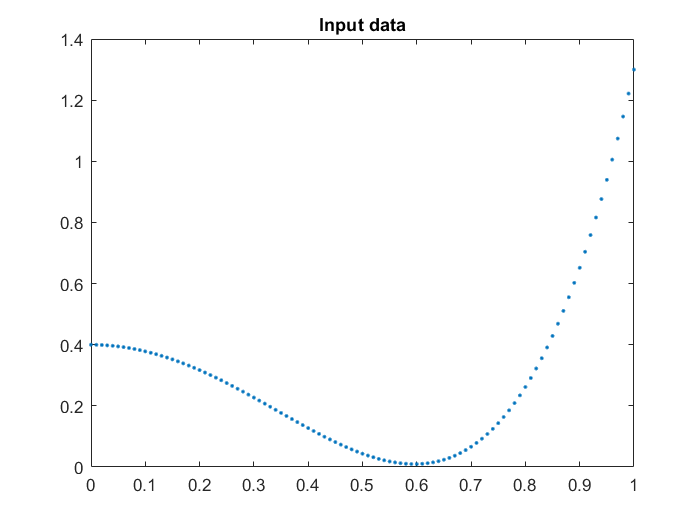

figure
plot(x, y, '.');
title('Input data');

Построение полинома 6-й степени

% built-in sixth degree polynomial
%[population, gof] = fit(x, y, 'poly6');

% custom model (polynomial)
model = 'p_6 * x^6 + p_5 * x^5 + p_4 * x^4 + p_3 * x^3 + p_2 * x^2 + p_1 * x + p_0';
[population, gof] = fit(x, y, model);

Отображение полинома 6-й степени на графике

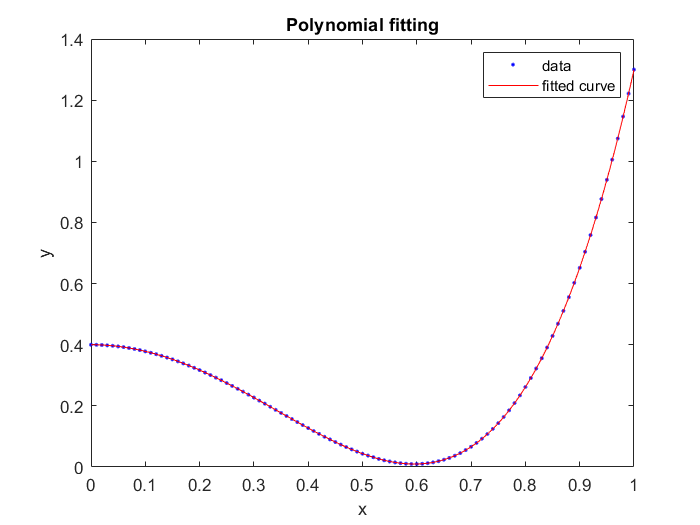

figure
plot(population, x, y);
title('Polynomial fitting');

Коэффициенты построенного полинома

disp(population);

     General model:
     population(x) = p_6 * x^6 + p_5 * x^5 + p_4 * x^4 + p_3 * x^3 + p_2 * x^2 
                    + p_1 * x + p_0
     Coefficients (with 95% confidence bounds):
       p_0 =         0.4  (0.4, 0.4)
       p_1 =   -2.72e-07  (-8.232e-07, 2.792e-07)
       p_2 =        -2.2  (-2.2, -2.2)
       p_3 =  -2.537e-05  (-4.392e-05, -6.813e-06)
       p_4 =         3.1  (3.1, 3.1)
       p_5 =  -6.106e-05  (-9.054e-05, -3.158e-05)
       p_6 =   2.299e-05  (1.32e-05, 3.278e-05)
